clc;
clear;
close all;

% Datos de la planta

s = tf("s");
% Datos de la plata obtenido con toolbox
Kp = 0.9058;
L = 0.11419; % Td
T = 1.2637; % Tp1
a = 0;      % a se encuentra dentro del rango
tao = L/T % tao se encuentra dentro del rango

tao = 0.0904


P=(Kp*exp(-L*s))/(1+T*s)

P =
 
                    0.9058
  exp(-0.114*s) * -----------
                  1.264 s + 1
 
Continuous-time transfer function.



# PI uSORT con MS=1.4

a0PI = 0.164;
a1PI = 0.305;
a2PI = -1.066;

b0PI = 14.650;
b1PI = 8.450;
b2PI = 0.0;
b3PI = 15.740;

% Controlador PI uSORT

Kp1 = ( a0PI + a1PI*tao^a2PI)/Kp 

Kp1 = 4.5481


Ti1 = ((b0PI + b1PI*tao+b2PI*tao^2)/(b3PI + tao))*T

Ti1 = 1.2304


% Ecuación PI
C = Kp1* (1 + 1/(Ti1*s))

C =
 
  5.596 s + 4.548
  ---------------
      1.23 s
 
Continuous-time transfer function.



C = Kp1* (( Ti1*s + 1)/(Ti1*s))

C =
 
  5.596 s + 4.548
  ---------------
      1.23 s
 
Continuous-time transfer function.



# Simulación a lazo cerrado

t = [0:0.01:30];
% Servocontrol
Myr = ( C * P ) /(1+ C * P );
% Regulador
Myd = minreal( P /(1+ C * P ) ); 

1 state removed.


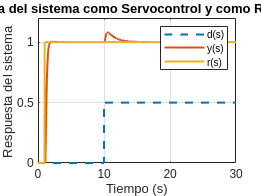


r = 0; %referencia
r ( t >= 1) = 1;

% La perturbacipón pasa de 0 a 0.5 cuando el tiempo es mayor o igual a 70.
d = 0; %perturbacion
d ( t >= 10) = 0.5;

% Para simular el servocontrol
yr = lsim ( Myr , r , t );
% Para simular el regulador
yd = lsim ( Myd , d , t );
y = yr + yd;
y1= yr;

figure (1) ;
plot (t,d,'--',t,y,t,r, LineWidth = 1.5)
hold on;
title ('Respuesta del sistema como Servocontrol y como Regulador PI') ;
xlabel ('Tiempo (s)') ;
ylabel ('Respuesta del sistema ') ;
legend ('d(s)','y(s)','r(s)') %leyenda
grid on;
hold off;

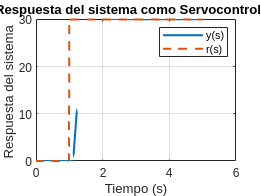


t1 = [0:0.01:5];

r1 = 0; %referencia
r1 ( t1 >= 1) = 30;

yr1 = lsim ( Myr , r1 , t1 );

y1= yr1;

figure (2) ;
plot (t1,y1,t1,r1, '--', LineWidth = 1.5)
hold on;
title ('Respuesta del sistema como Servocontrol PI') ;
xlabel ('Tiempo (s)') ;
ylabel ('Respuesta del sistema ') ;
legend ('y(s)','r(s)') %leyenda
grid on;
hold off;

# Medir robustez del PI

L = P*C

L =
 
                    5.069 s + 4.12
  exp(-0.114*s) * ------------------
                  1.555 s^2 + 1.23 s
 
Continuous-time transfer function.



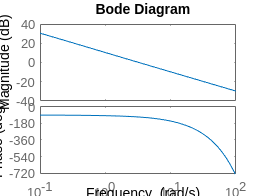


% Se uso sisotool para obtener el tiempo de asentamiento al 2%
%sisotool(C)
bode(L)

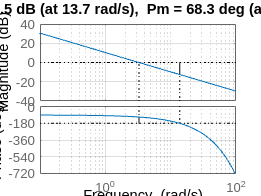

margin(L)
grid on

figure(1)

# tiempo de asentamiento

ind = find(y1>max(y1)-0.02*(max(y1)),1)-1;
ta2 = t(ind) -1 %se resta el -1 del escalon

ta2 = 0.7200

# Esfuerzo de control

M = minreal( (C) / (1+C*P));

1 state removed.


u = lsim(M,r1,t1);
TVud = sum(abs(diff(u)));

# Calculo del IAE

% Carga de datos
data = readmatrix('Flujo_delta_25a50.xlsx','Range','A377:C1471');

tp = data(:,1)-30;
u = data(:,2);
y = data(:,3);


yn = y - mean(y(1:10));
un = u - mean(u(1:10));


Myr= L/(1+L);

y1=lsim(Myr,un,tp);


figure (4) ;
plot (tp,un, tp, y1)
hold on;
title ('Respuesta del sistema como Servocontrol con controlador PI') ;
xlabel ('Tiempo (s)') ;
ylabel ('Respuesta del sistema ') ;
legend ('d(s)','y(s)','r(s)') 

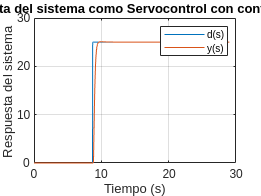

grid on;
hold off;




% IAE
SalidaPlanta= un;
SalidaModelo= y1; 
e_IAE=abs(SalidaPlanta-SalidaModelo);
IAE=trapz(tp,e_IAE)

IAE = 8.0603